%clear variables
load('3-bead/systems.mat');
nt = 1000000;
dt = 0.01;
trials = 10; 

alpha = linspace(0.01, 0.1, 91);

s = zeros(1,size(alpha,2));
p = zeros(1,size(alpha,2));

for i = 1:size(alpha,2)
    s1 = zeros(1,trials);
    p1 = zeros(1,trials);
    for j = 1:trials
        param = alpha(i);
        system2.a = @(x)param*2./(1+exp(20*(abs(x)-0.75)));
        system2.param = param; 
        x = [0 -1 0 -1 0 1];
        x = find_minima(system2, x);
        [pos_t, state_t] = simulate_system_param(system2, x, 0.001, nt, dt, []);
        state_t = sum(state_t == [1 2 3]');
        s1(j) = sum(state_t == 3);
        p1(j) = unbound(pos_t, dt, nt);
    end
    s(i) = sum(s1)/trials/nt;
    p(i) = sum(p1)/trials/nt;
end


scatter(alpha, s, 'filled')

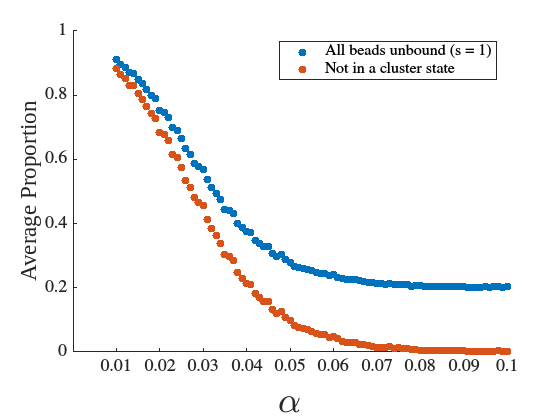

hold on 
scatter(alpha, p, 'filled')
hold off
legend("All beads unbound (s = 1)", "Not in a cluster state", "Location", "northeast")
xticks([0.01 0.02 0.03 0.04 0.05 0.06 0.07 0.08 0.09 0.1])
yticks([0 0.2 0.4 0.6 0.8 1])
yticklabels({"0", "0.2", "0.4", "0.6", "0.8", "1"});
%xticklabels("0.01", "0.02", "0.03", "0.04", "0.05", "0.06", "0.07", "0.08", "0.09", "0.1")

set(gca, "FontName", "Times", "FontSize", 14);
xlabel('\alpha', 'FontSize', 28, 'fontname','Times New Roman');
ylabel('Average Proportion', "FontName", "Times new Roman", "FontSize", 18)